## Esercizio sull'analisi delle corrispondenze

% La zona A1:B1037 del file soft-drinks.xlsx contiene i risultati di un'indagine in cui si è chiesto
% di associare ad ogni brand nel mercato delle "soft drinks" una determinata parola.
% 
% 1) Costruire la distribuzione di frequenza della variabile Marca.
% Rappresentare graficamente tramite grafico a barre e grafico a torta la
% distribuzione di frequenza in percentuale in due pannelli orizzontali. 
% Aggiungere il titolo del grafico ad entrambi i pannelli.
% Inserire come titolo complessivo dei due pannelli
% VARIABILE MARCA
% 
% 2) Costruire la tabella di contingenza tra le due variabili (Variabile Parola sulle righe).
% 
% 3) Costruire manualmente la tabella delle frequenze teoriche e calcolare
% manualmente l'indice Chi2 ed il relativo p-value. Denominare la variabile
% che contiene la table delle frequenze teoriche comprensiva delle intestazioni di riga e
% di colonna Ntable
%
% 4) Analizzare l'entità dell'associazione tramite l'indce di Cramer.
% Commentare l'indice. Denominare la variabile che contiene l'indice di
% Cramer CRA
% 
% 5) Costruire e commentare il grafico di analisi delle corrispondenze.  
% Commentare la quota di inerzia spiegata e le relazioni tra i punti riga ed i punti colonna. 
% 
% 6) Discutere i due punti riga più dominanti nella spiegazione
% dell'inerzia della prima dimensione latente.
%
% 7) Costruire e commentare il moonplot
%
% 8) Utilizzando la funzione CorAnaplot, ripetere il grafico di analisi
% delle corrispodenza adottando una mappa di colore.
% Nel primo grafico le etichette di riga devono avere un colore che dipende dalla loro
% massa.
% Nel secondo grafico le etichette di riga devono avere un colore che dipende
% dal contributo dei punti riga all'inerzia delle prime due dimensioni
% latenti 
% Suggerimento: utilizzando l'opzione plots di CorAnaplot.

close all
clear
X = readtable('soft-drinks.xlsx','Sheet','Foglio1','range','A1:B1037');

% 1) Costruire la distribuzione di frequenza della variabile Marca.
% Rappresentare graficamente tramite grafico a barre e grafico a torta la
% distribuzione di frequenza in percentuale in due pannelli orizzontali. 
% Agiungere il titolo del grafico ad entrambi i pannelli.
% Inserire come titolo complessivo dei due pannelli
% VARIABILE MARCA

% Distribuione di frequenza della variabile Marca
Xca=categorical(X.Marca);
disp('Distribuzione di frequenze della variabile marca')

Distribuzione di frequenze della variabile marca


summary(Xca);

     Coke          332 
     DietCoke       45 
     Fanta         126 
     Pepsi          69 
     RedBull       213 
     V             251 


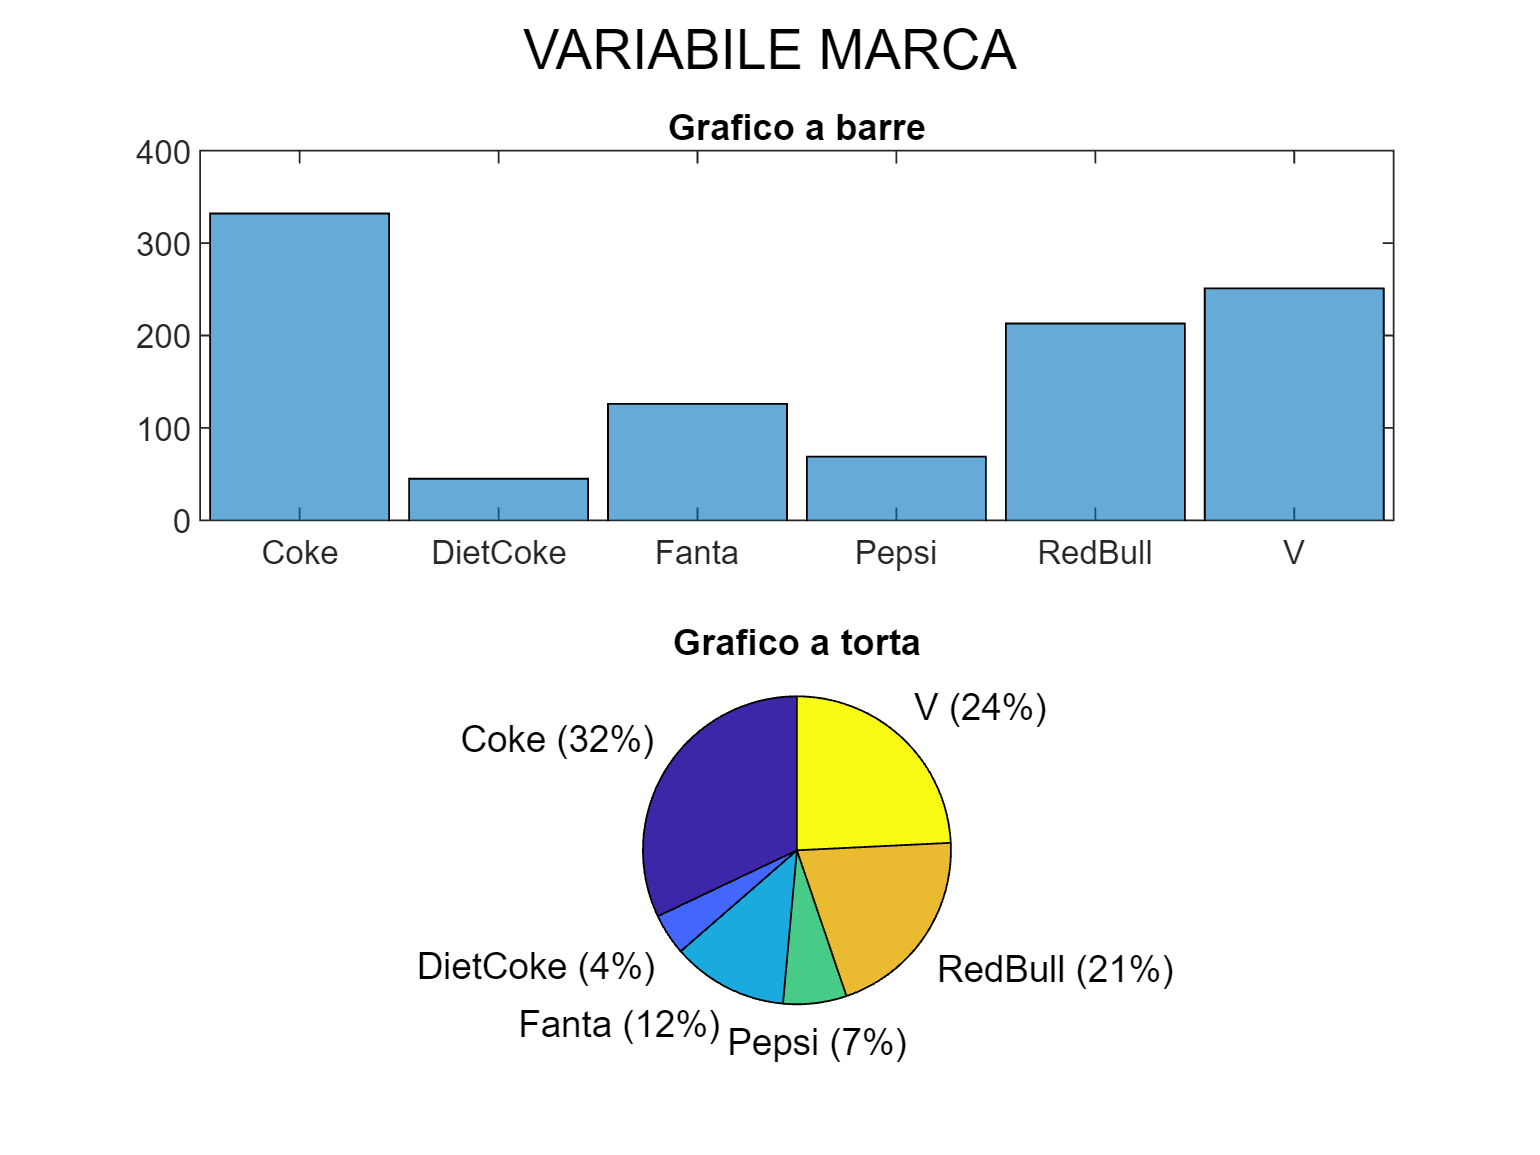


% Osservazione: andava bene anche 
% tabulate(X.Marca)

% Rappresentare graficamente tramite grafico a barre e grafico a torta la
% distribuzione di frequenza in percentuale in due pannelli orizzontali. 
% Aggiungere il titolo del grafico ad entrambi i pannelli.
% Inserire come titolo complessivo dei due pannelli
% VARIABILE MARCA

subplot(2,1,1)
% Grafico a barre
histogram(Xca);  
title('Grafico a barre');
% Grafico a torta
subplot(2,1,2)
pie(Xca); % GRAFICO A TORTA
title('Grafico a torta');
sgtitle('VARIABILE MARCA')


% Commento: Coke, V e RedBull sono le tre marche che presentano la maggiore frequenza

% 2) Costruire la tabella di contingenza tra le due variabili (Variabile Parola sulle righe).

% Tabella di contingenza
[N,chi2CHK,pvalCHK,labels] =crosstab(X.Parola,X.Marca);
% chi2CHK e pvalCHK sono rispettivamente il valore dell'indice chi quadrato
% ed il p-value da confrontare con l'implementazione manuale.
[I,J]=size(N);

% Costruzione della tabella di contingenza in formato table
% Dall'array N alla tabella Ntable
NtableEmp=array2table(N,'RowNames',labels(1:I,1),'VariableNames',labels(1:J,2));
disp('Tabella di contingenza tra Parola e Marca')

Tabella di contingenza tra Parola e Marca


disp(NtableEmp)

                   Coke    V     RedBull    Fanta    Pepsi    DietCoke
                   ____    __    _______    _____    _____    ________

    Teens           69     46      41        13       22         18   
    PicksYouUp      29     52      45         3        5          3   
    Energy          19     55      47         2        3          1   
    EnjoyLife       50     22      19         8       10          7   
    WhenTired       25     38      33         2        4          3   
    Kids            30      2       1        45        8          2   
    Fun             35      6       5        32        5          2   
    Refreshes       


% 3) Costruire manualmente la tabella delle frequenze teoriche e calcolare
% manualmente l'indice Chi2 ed il relativo p-value. Denominare la variabile
% che contiene la table delle frequenze teoriche comprensiva delle intestazioni di riga e
% di colonna Ntable
%

%% Calcolo della tabella delle frequenze teoriche 

% n= numero di unità del campione
n=sum(sum(N));
sumc=sum(N,1);
sumr=sum(N,2);
Ntheo=(sumr*sumc/n);
rownam=labels(1:I,1);
Ntable=array2table(Ntheo,'RowNames',rownam,'VariableNames',labels(1:J,2));
disp('Tabella delle frequenze teoriche nel caso di indipendenza')

Tabella delle frequenze teoriche nel caso di indipendenza


disp(Ntable)

                    Coke       V       RedBull    Fanta     Pepsi     DietCoke
                   ______    ______    _______    ______    ______    ________

    Teens          66.977    50.636     42.97     25.419     13.92     9.0782 
    PicksYouUp     43.903    33.192    28.167     16.662    9.1245     5.9508 
    Energy         40.699    30.769    26.111     15.446    8.4585     5.5164 
    EnjoyLife      37.174    28.104    23.849     14.108    7.7259     5.0386 
    WhenTired      33.649    25.439    21.588      12.77    6.9932     4.5608 
    Kids           28.201     21.32    18.093     10.703     5.861     3.8224 
    Fun            27.239    20.594    17.47


%% Calcolo in maniera manuale indice Chi2 e p value
Chi2=sum(((N-Ntheo).^2)./Ntheo,'all');
disp(['Indice Chi2:' num2str(Chi2)])

Indice Chi2:396.628


disp('Controllo uguaglianza sulle due implementazioni indice Chi2')

Controllo uguaglianza sulle due implementazioni indice Chi2


disp(isequal(Chi2,chi2CHK));

   1



% Calcolo p value del test = probabilità di ottenere un valore supereriore
% a Chi3 nella v.c. chi quadrato con (I-1)*(J-1) ossia 45 gradi di libertà
gdl=(I-1)*(J-1);
pval=chi2cdf(Chi2,gdl,'upper');
disp('differenze tra le due implementazioni del p-value')

differenze tra le due implementazioni del p-value


disp(pval-pvalCHK);

     0



% p value vitualmente uguale a zero===> forte associazione tra le variabili "parola" e
% "marca". Rifiutiamo sicuramente l'ipotesi nulla di indipendenza tra le due
% variabili ==> Ogni brand è associato ad una o più parole. L'obiettivo
% dell'analisi delle corrispondenze è capire quali parole sono associate a
% quali marchi.

% 4) Analizzare l'entità dell'associazione tramite l'indce di Cramer.
% Commentare l'indice. Denominare la variabile che contiene l'indice di
% Cramer CRA

%% calcolo indice Cramer tramite la funzione corrNominal
out=corrNominal(N);

Chi2 index
  396.6280

pvalue Chi2 index
   8.6872e-58

Phi index
    0.6187

Cramer's V 
    0.2767

Test of H_0: independence between rows and columns
                   Coeff         se        zscore       pval   
                  ________    _________    ______    __________

    CramerV        0.27671      0.02242    12.342             0
    GKlambdayx     0.12358     0.022762    5.4291    5.6634e-08
    tauyx         0.083252    0.0088288    9.4296             0
    Hyx            0.11278     0.010518    10.722             0

-----------------------------------------
Indexes and 95% confidence limits
                   Value      StandardError    ConflimL    ConflimU
                  ________  

CRA=out.CramerV(1,1);
disp("Indice di Cramer");

Indice di Cramer


disp(CRA);

    0.2767



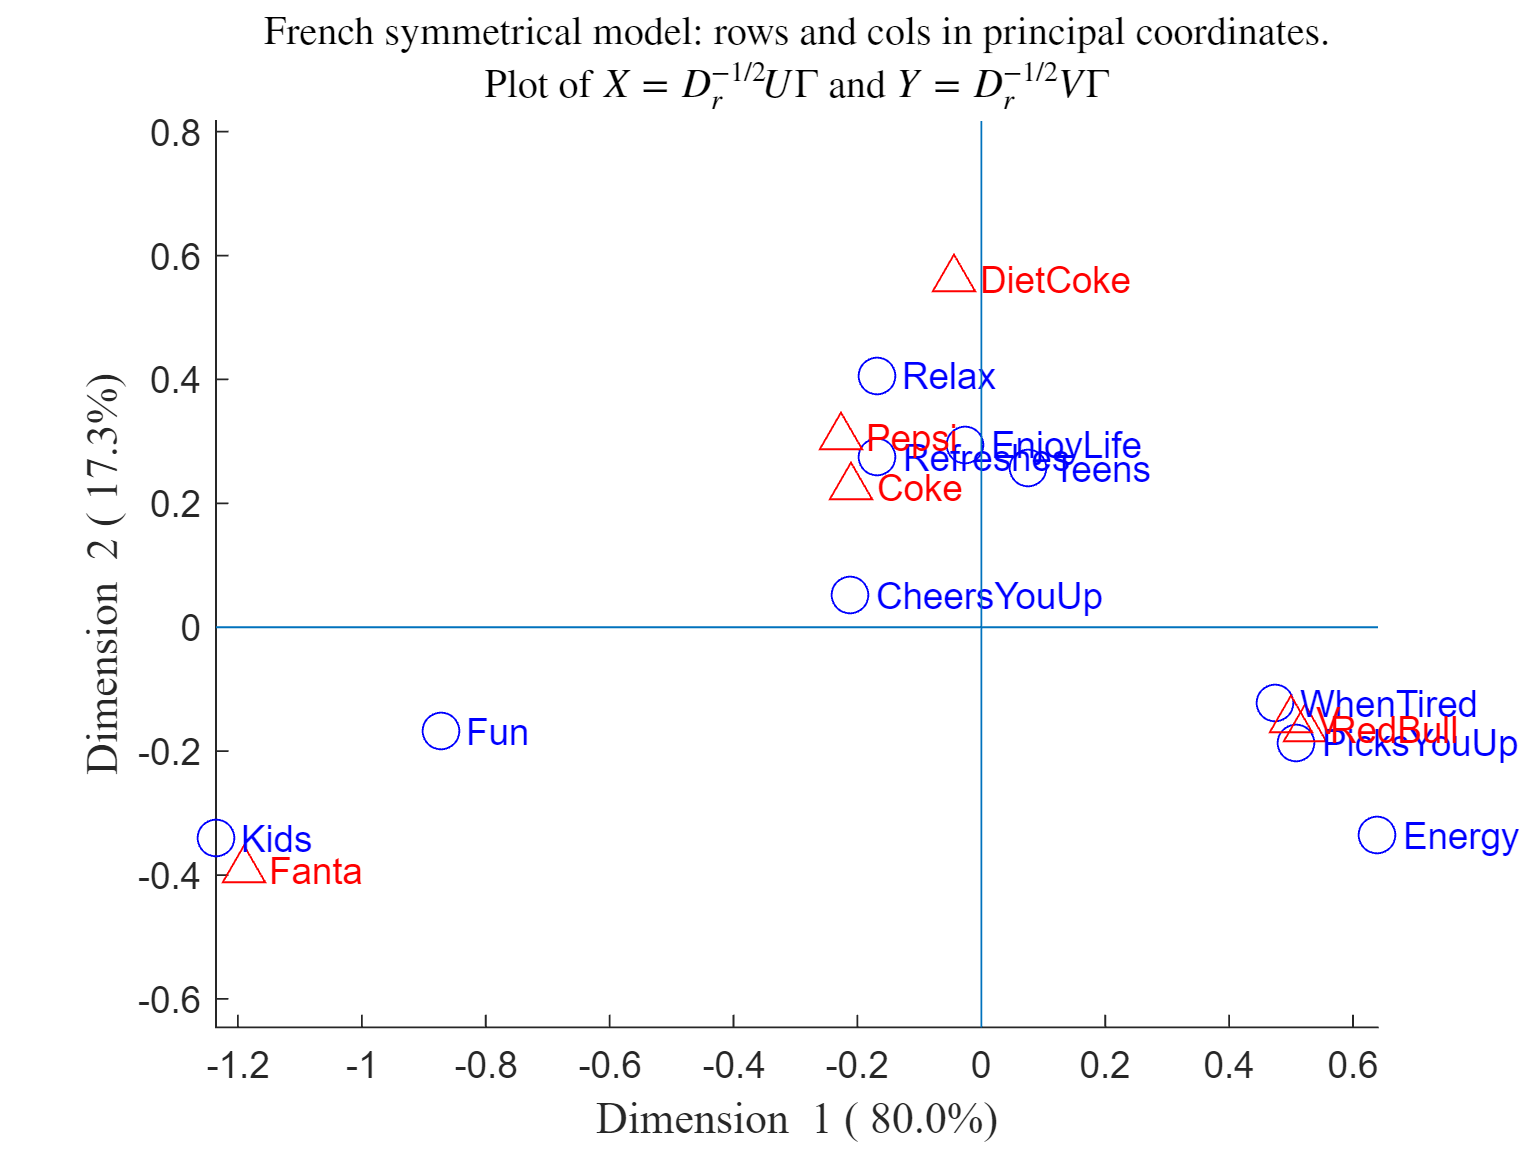

Summary
             Singular_value     Inertia      Accounted_for    Cumulative
             ______________    __________    _____________    __________

    dim_1        0.55337          0.30622        0.79984       0.79984  
    dim_2          0.257         0.066048        0.17252       0.97236  
    dim_3       0.099125        0.0098259       0.025665       0.99803  
    dim_4       0.021092       0.00044486       0.001162       0.99919  
    dim_5       0.017632        0.0003109     0.00081207             1  

ROW POINTS
Results for dimension: 1
                    Scores      CntrbPnt2In    CntrbDim2In
                   _________    ___________    ___________

 


% l'indice di Cramer ci dice che l'associazione tra le due variabili della
% tabella è pari al 27.67 per cento del valore massimo posssibile.

% 5) Costruire e commentare il grafico di analisi delle corrispondenze.  
% Commentare la quota di inerzia spiegata e le relazioni tra i punti riga ed i punti colonna. 
% 

%% Analisi delle corrispondenze
outCA=CorAna(N,'Lr',labels(1:I,1),'Lc',labels(1:J,2));




%% Mostro la tabella che contiene i dettagli dell'inerzia spiegata
disp(outCA.Summary)

             Singular_value     Inertia      Accounted_for    Cumulative
             ______________    __________    _____________    __________

    dim_1        0.55337          0.30622        0.79984       0.79984  
    dim_2          0.257         0.066048        0.17252       0.97236  
    dim_3       0.099125        0.0098259       0.025665       0.99803  
    dim_4       0.021092       0.00044486       0.001162       0.99919  
    dim_5       0.017632        0.0003109     0.00081207             1  



% Con le prime due dimensioni latenti arriviamo a spiegare il 97,3% di
% variabilità (inerzia) della tabella di contingenza. Ottima riduzione
% delle dimensioni.
% Il grafico di analisi delle corrispondenze presenta una rappresentazione
% 2D molto accurata della posizione dei punti nello spazio originario a (I-1) e (J-1)
% dimensioni.
%
% Commento: 
% Ci sono 3 "gruppi" ben precisi: 
% 1) il brand "Fanta" è associato alle parole Kids e Fun (bambini e
% divertimento)
% 2) I marchi "Diet Coke", "Pepsi" e "Coke" sono associati prevalentemente alle
% parole "Relax", "Enjoy Life", "Teens" e "Cheers you Up"
% I marchi "V" e "Red Bull" sono associati alle parole "When Tired", "Picks you
% up" e "Energy".
% L'angolo tra il gruppo Coke/Pepsi e Redbull è vicino a 90 gradi==>
% assenza di relazione.
% L'angolo tra il gruppo Coke/Pepsi e Fanta è vicino a 90 gradi==>
% assenza di relazione.
% L'angolo tra Red Bull/V e Fanta è circa 180 gradi ==> forte relazione
% inversa. I marchi Red Bull e V sono considerati per adulti. Il marchio Fanta è
% associato ai bambini.
% La prima dimensione latente quindi è legata in qualche modo all'età, da
% adolescenti ad adulti andando da sinistra verso destra.
% 
% Nella seconda dimensione latente andando dal basso verso l'alto, 
% si può notare come si passa da bevande ad alto contenuto energetico e di zuccheri a una
% 'diet coke' con assenza di zuccheri". 
%
% 
% Il punto più vicino all'origine è CheersYouUp che dovrebbe, 
% indipendentemente dall'età, essere il motivo principale per cui si beve una
% soft drink (interpretazione ad libitum)
%  

% 6) Discutere i due punti riga più dominanti nella spiegazione
% dell'inerzia della prima dimensione latente.

% I punti riga dominanti che spiegano maggiormente l'inerzia della prima dimensione
% latente sono le parole Kids (42%) e i Fun (20%).
disp('Mostro in ordine crescente il contributo dei punti riga')

Mostro in ordine crescente il contributo dei punti riga


disp('alla spiegazione dell''inerzia della prima dimensione latente')

alla spiegazione dell'inerzia della prima dimensione latente


disp(sortrows(outCA.OverviewRows(:,'CntrbPnt2In_1')))

                   CntrbPnt2In_1
                   _____________

    EnjoyLife       0.00022819  
    Relax            0.0034851  
    Teens            0.0038057  
    Refreshes        0.0055429  
    CheersYouUp      0.0093575  
    WhenTired         0.074706  
    PicksYouUp         0.11209  
    Energy             0.16404  
    Fun                0.20337  
    Kids               0.42338  



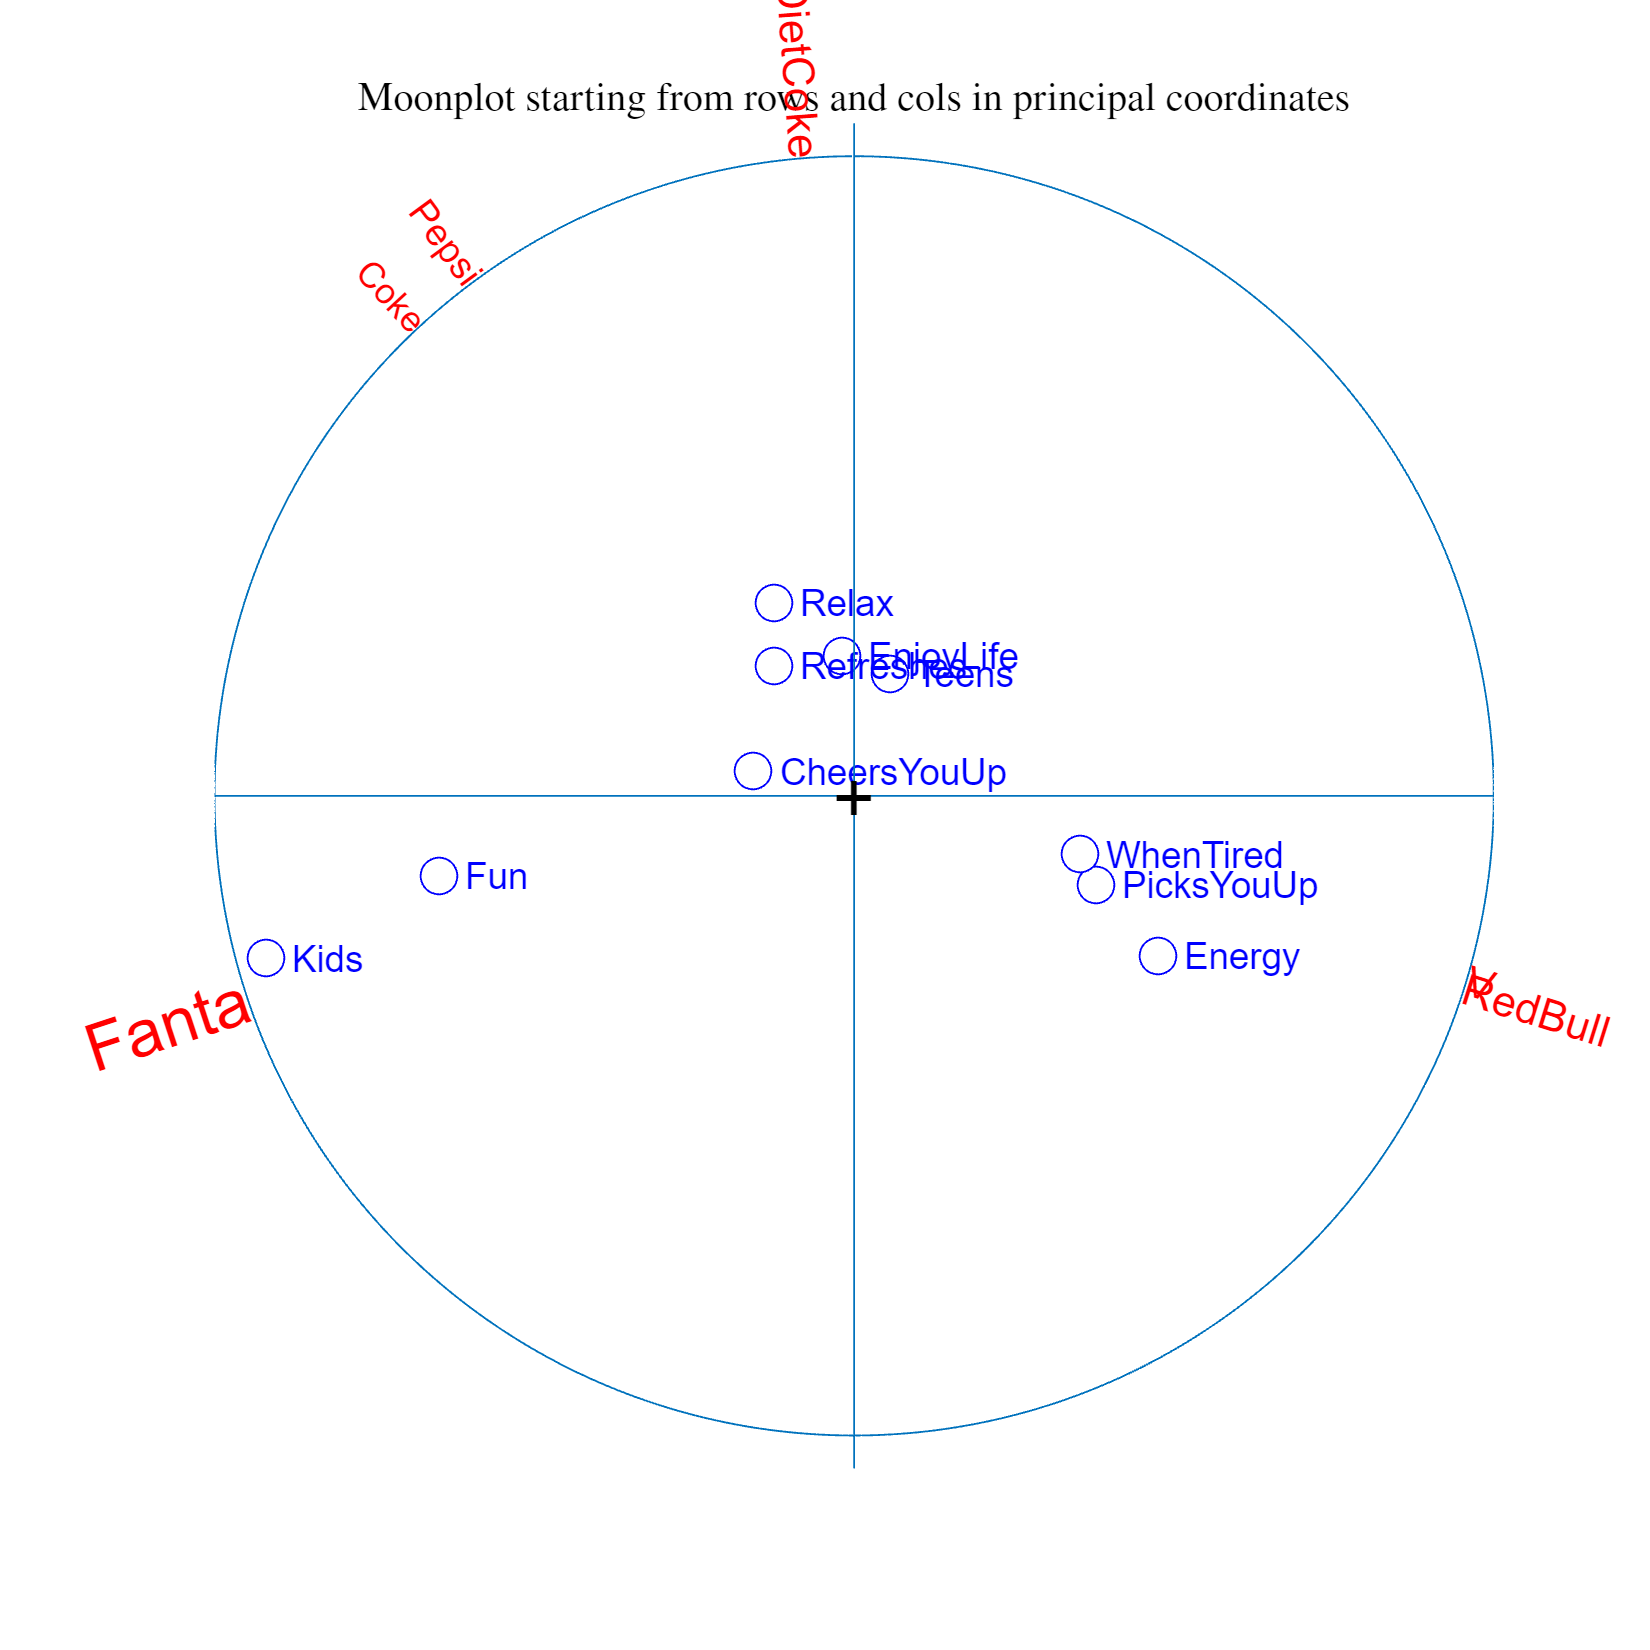


%
% 7) Costruire e commentare il moonplot

figure
moonplot(outCA)

--------------------------------
The colormap of the row labels is proportional to Mass


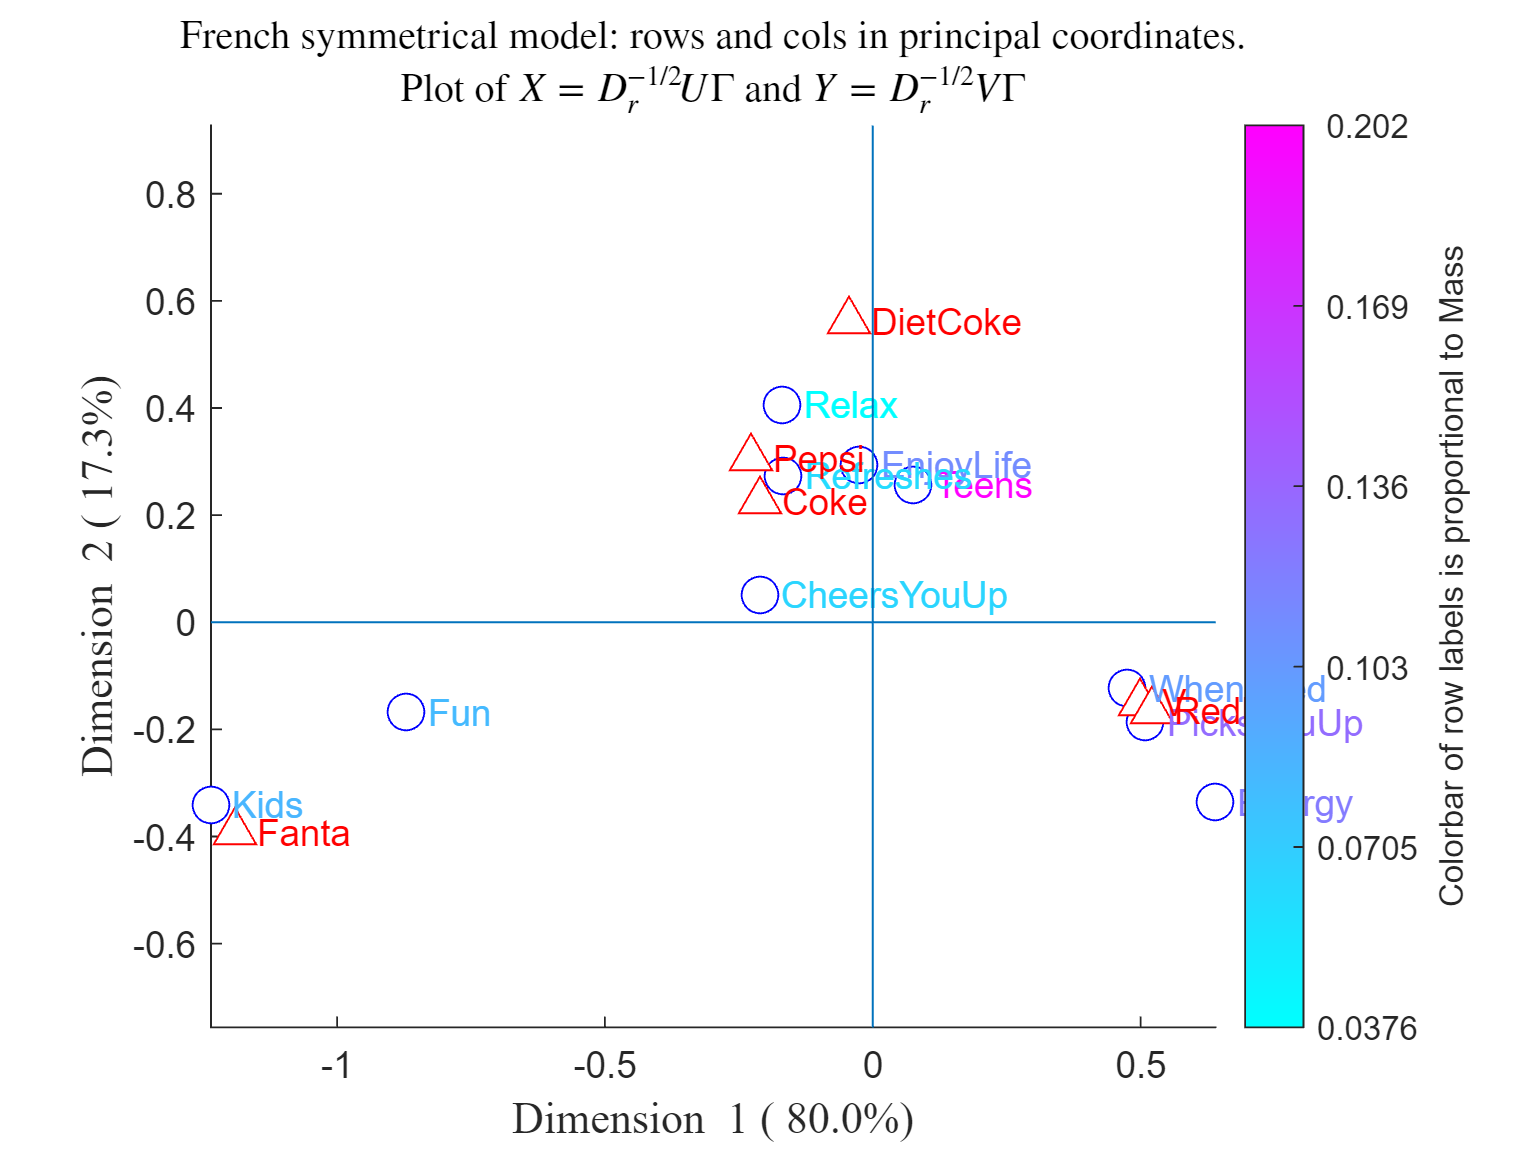

% Il moonplot ribadisce che l'angolo tra il vettore associato al punto
% colonna Fanta forma un angolo molto piccolo con i due vettori associati
% ai punti riga "Kids" e "Fun"
% Similmente il moonplot ribadisce che V e RedBull si trovano nella stessa
% direzione


% 8) Utilizzando la funzione CorAnaplot, ripetere il grafico di analisi
% delle corrispodenza adottando una mappa di colore.
% Nel primo grafico le etichette di riga devono avere un colore che dipende dalla loro
% massa.

% Colormap dei punti riga proporzionale alle masse di riga
figure
plots=struct;
plots.ColorMapLabelRows='Mass';
CorAnaplot(outCA,'plots',plots)

% Commento: Teens PicksYouUp and Energy sono i punti riga con le masse più
% grandi

% Nel secondo grafico le etichette di riga devono avere un colore che dipende
% dal contributo dei punti riga all'inerzia delle prime due dimensioni

% Colormap dei punti riga proporzionale al contributo dei punti riga
% alla spiegazione dell'inerzia delle prime due dimensioni latenti
% Dall'help della funzione CorAnaplot
%
%                   plots.ColorMapLabelRows='CntrbPnt2In' it is possible
%                   to have a colormap where row labels are proportional to
%                   the contribution of the row points to the inertia of
%                   the two latent dimensions.
plots=struct;
plots.ColorMapLabelRows='CntrbPnt2In';
CorAnaplot(outCA,'plots',plots)

--------------------------------
The colormap of the row labels is proportional to the contribution
of the row points to the inertia of the two latent dimensions


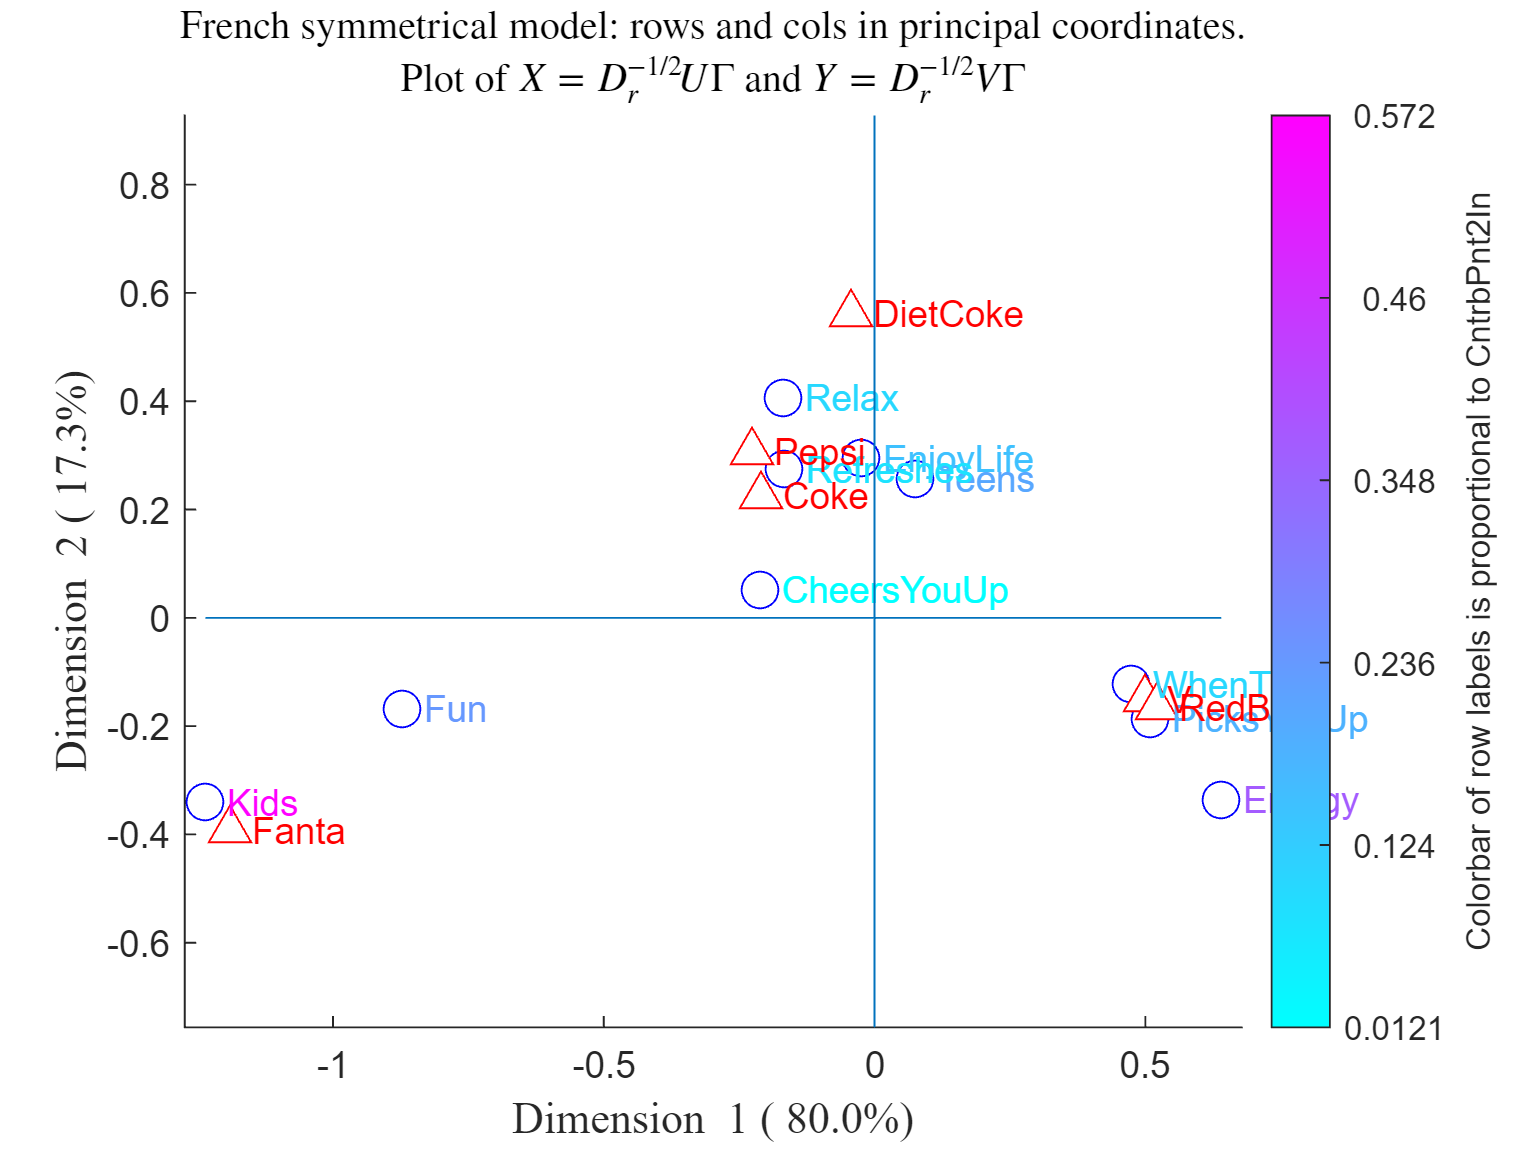

axis equal

% Contributo dei punti riga all'inerzia delle prime due dimensioni
CntrbPnt2In=sum(outCA.OverviewRows{:,["CntrbPnt2In_1"    "CntrbPnt2In_2"]},2);

% I due punti riga che danno il maggior contributo all'inerzia delle prime
% due dimensioni sono Kids e Energy
sortrows(array2table(CntrbPnt2In,"RowNames",rownam))

ans = 10×1 table
                   CntrbPnt2In
                   ___________

    CheersYouUp     0.012072  
    Refreshes         0.0751  
    WhenTired       0.097557  
    Relax           0.097853  
    EnjoyLife        0.14814  
    PicksYouUp       0.18098  
    Teens            0.20651  
    Fun              0.23795  
    Energy           0.37187  
    Kids             0.57196  
